clear all;

% Call the script to get the CFD Look Up Table
[wut_cr_lut_data, uvic_cfd_lut_data, uvic_cfd_true_data, uvic_amp_lut_data] = f00_pmtCFDAlgorithmLUT();
% waveforms = f01_pmtCFDWaveforms();
% waveform = waveforms(:,1);

root_data = readmatrix("C:\Users\miech\Documents\HyperK\Repozytoria\mpmt_teststand\waveforms.csv");
waveforms = root_data';
waveforms(isnan(waveforms)) = 0;
% janusz_marzec_data_path_old = "C:\Users\miech\OneDrive - Politechnika Warszawska\PMT-badanie\C1--hv--final00--00000samples.csv";
% janusz_marzec_data_path = "C:\Users\miech\Documents\HyperK\Dane\JMarzec\CFD\C1--hv--10700---00000samples.csv";
% jm_data = readmatrix(janusz_marzec_data_path_old);
% waveforms = jm_data';


% x = [1:4:length(waveforms)]';
% plot(x, waveforms(x,:))
waveforms = waveforms(1:32,:);

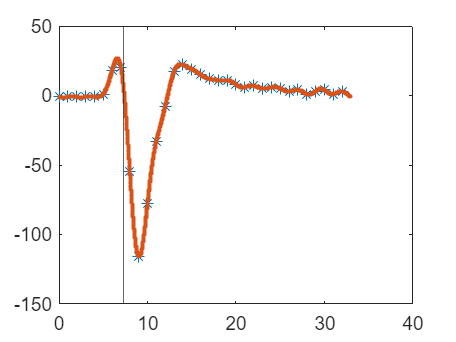

cfd_time = [];
fine_time = [];

index = 1;
for n = 1 : size(waveforms,2)
    if(max(waveforms(:,n)) > 1800)
        continue
    end
    waveform = waveforms(:,n);
    [cfd_time_uvic(index), fine_time_uvic(index)] = cfd_algorithm_uvic(waveform);
    [cfd_time_wut(index), fine_time_wut(index)] = cfd_algorithm_wut(waveform);
    index = index + 1;
end

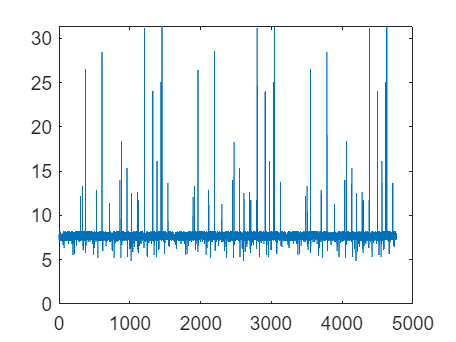

plot(cfd_time_wut)

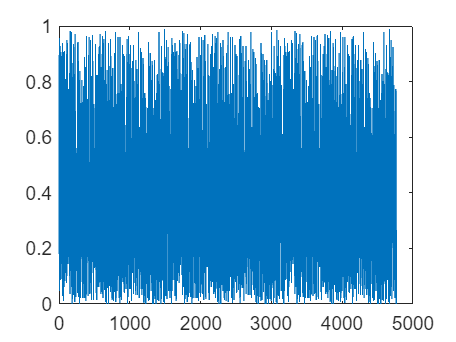

plot(fine_time_wut)

plot(cfd_time_wut)

plot(fine_time_wut)

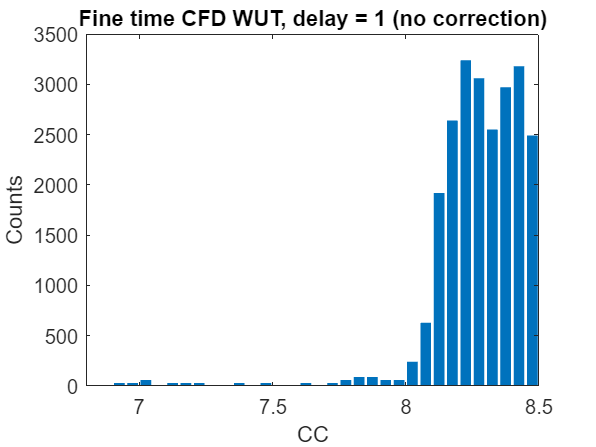

[fine_time_n, edges] = histcounts(cfd_time_wut,'BinWidth',0.05);
fine_time_bin_centers = edges(1:end-1)+0.025;
bar(fine_time_bin_centers, fine_time_n); title("Fine time CFD WUT, delay = 1 (no correction)")
xlabel("CC")
ylabel("Counts")
xlim([6.8 8.5])

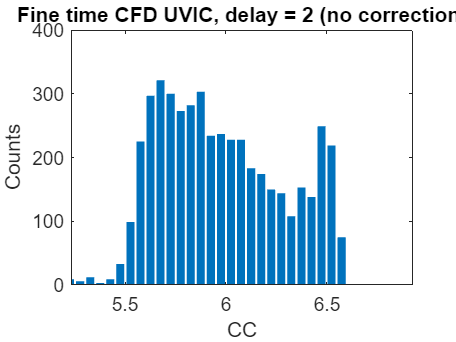

[fine_time_n, edges] = histcounts(cfd_time_uvic,'BinWidth',0.05);
fine_time_bin_centers = edges(1:end-1)+0.025;
bar(fine_time_bin_centers, fine_time_n); title("Fine time CFD UVIC, delay = 2 (no correction)")
xlabel("CC")
ylabel("Counts")
xlim([6.8 8.5] - 1.5703)

% FFT interpolation of the waveforms
% waveform = waveforms(1:32,1);
% waveform_length = length(waveform);
% waveform_interpolated = interpft(waveforms(1:waveform_length,1),waveform_length*25);
% waveform_interpolated_length = length(waveform_interpolated);
% 
% x1 = 0:waveform_length-1;
% x2 = (0:waveform_interpolated_length-1) / (25);
% 
% plot(x1, waveform, "*", x2, waveform_interpolated, ".-")

function [cfd_time, fine_time] = cfd_algorithm_wut(waveform)

    % Call the script to get the CFD Look Up Table
    wut_cr_lut_data = f00_pmtCFDAlgorithmLUT();
    
    cfd = [];
    cfd.delay = 1;
    cfd.gain_delayed = 2;
    time_base_ns = 8;
    cr_lut_size = length(wut_cr_lut_data);
    
    samples = waveform;
    delayed = [-cfd.gain_delayed * samples(1:cfd.delay); -cfd.gain_delayed * samples;];
    
    samples = [samples; samples(end-cfd.delay+1:end)];
    cf_samples = samples + delayed;
    
    % Find minimum and maximum of constant fraction waveform and deduct whether we have negative or positive pulses
    [~, idx_min] = min(cf_samples);
    idx = idx_min;
    
    if idx > 1
        % Find first point  that is above zero
        while true
            % We did - decrease its index by one (i.e. move left)
            idx = idx - 1;
            if (idx == 1)
                break;
            end
            if (cf_samples(idx) >= 0) 
                break;
            end
        end
    
        % Use linear interpolation to get sub-sample index of the zero-crossing point
        x1 = idx;
        x2 = x1+1;
        y1 = cf_samples(sub2ind(size(cf_samples), x1, 1:size(cf_samples,2)));
        y2 = cf_samples(sub2ind(size(cf_samples), x2, 1:size(cf_samples,2)));
        y_ratio = (double(y1) ./ double(y1-y2));
        % linear interpolation
        cf_time_vector = x1 + y_ratio;
        t0_pos = (cf_time_vector-1)*time_base_ns;
        cf_time_coarse = x1;
        cr = y_ratio;
        
        % perform time correction accordingly to cr value
        cr_idx = round(cr*(cr_lut_size-1))+1;
        if cr_idx <= 0
            cr_idx = 1;
        end
        if cr_idx > cr_lut_size
            cr_idx = cr_lut_size;
        end
        % IF CORRECTION APPLIED THEN
        % cf_time_ns = t0_pos(1) + wut_cr_lut_data(cr_idx) * 8;
        % cf_time = cf_time_ns / 8.0;
        % cf_time_min = cf_time_ns/8.0 - (cf_time_coarse - 1);
        
        %IF NO CORRECTION THEN
        cf_time_ns = t0_pos(1);
        cf_time = cf_time_ns / 8.0;
        cf_time_min = cf_time_ns/8.0 - (cf_time_coarse - 1);
        % 
        % amplitude_cr = samples(x1) * cr_amp_lut_data(cr_idx);
        % amplitude_max = max(samples);
       
        % integration start from first sample
        samples_intergral = 0;
        for idx = 1:numel(samples)
            % falling edge - check if below thr
            if idx > x2 && samples(idx) < 0
                break
            end
            samples_intergral = samples_intergral + samples(idx);
        end
    
    else
        cf_time_ns = NaN;
        cr = NaN;
        amplitude_cr = NaN;
        amplitude_max = NaN;
        samples_intergral = NaN;
    end
    
    % SET THE RESULT RETURNED
    cfd_time = cf_time;
    fine_time = cf_time_min;
    
    cfd_waveform_length = length(cf_samples);
    cfd_waveform_interpolated = interpft(cf_samples,cfd_waveform_length*100);
    cfd_waveform_interpolated_length = length(cfd_waveform_interpolated);

    x1 = 0:cfd_waveform_length-1;
    x2 = (0:cfd_waveform_interpolated_length-1) / (100);
    
    plot(x1, cf_samples, "*", x2, cfd_waveform_interpolated, ".-")
    xline(cfd_time)
end

function [cfd_time, fine_time] = cfd_algorithm_uvic(waveform)

    [~, uvic_cfd_lut_data, uvic_cfd_true_data, uvic_amp_lut_data]  = f00_pmtCFDAlgorithmLUT();
    
    % Find peak time beans
    
    threshold = 20;
    % for peak finding, the baseline is assumed to be zero
    
    baseline = 0;
    
    % threshold is the minimum positive signal above baseline
    below = (waveform(1) - baseline) <= threshold;
    peak_timebins = [];
    max_val = 0;
    max_timebin = -1;
    
    for k = 1 : length(waveform)
        if (below && (waveform(k) - baseline > threshold))
            below = false;
            max_val = 0;
            max_timebin = -1;
        end
        if ~below
            if (waveform(k) - baseline > max_val)
                max_val = waveform(k) - baseline;
                max_timebin = k - 1;
            end
            if (waveform(k) - baseline <= threshold)
                below = true;
                peak_timebins = [peak_timebins; max_timebin];
            elseif (k == length(waveform))
                peak_timebins = [peak_timebins; max_timebin];
            end
        end
    end
    
    analysis_offset = peak_timebins - 7;
    adcs = waveform(analysis_offset + 1:analysis_offset + 10);
    
    % Calculate CFD
    %     # Use a cfd like algorithm with delay d = 2, multiplier c = -2
    c = -2;
    d = 2;
    
    %     # for cfd just use the average of the first 3 adcs as the baseline
    baseline = (adcs(1) + adcs(2) + adcs(3)) / 3.;
    %     # the amplitude is found by adding the highest 3 adcs and subtracting the baseline
    %     # amp = (baseline - np.min(adcs)) / 100.
    sorted_vals = sort(adcs - baseline, 'descend');
    n_largest_vals = sorted_vals(1:3);
    amp = sum(n_largest_vals);
    
    %     # converting to positive going pulses
    for k = d + 1 : length(adcs)
        reversed(k - d) = c * (adcs(k-d) - baseline);
        cfd_waveform(k-d) = (adcs(k) - baseline) + c * (adcs(k-d) - baseline);
    end
    
    %     # find largest swing zero crossing
    max_diff = 0;
    i_md = -1;
    for iv  = 2 : length(cfd_waveform)
        if cfd_waveform(iv - 1) > 0. && cfd_waveform(iv) < 0.
            if cfd_waveform(iv - 1) - cfd_waveform(iv) > max_diff
                max_diff = cfd_waveform(iv - 1) - cfd_waveform(iv);
                i_md = iv;
            end
        end
    end

    if i_md > -1
        x0 = (i_md - 1) - 1;
        y0 = cfd_waveform(i_md - 1);
        x1 = (i_md) - 1;
        y1 = cfd_waveform(i_md);
    
    %         # using a linear interpolation, find the value of x for which y = 0
        x = x0 - (x1 - x0) / (y1 - y0) * y0;
        % x = x0 + y0 * (x1 - x0) / (y0 - y1);
    %         # apply offset assuming sigma = 0.96 (see try_cfd.ipynb)
        % x = x - 0.5703;
    %         # apply a correction
        apply_correction = false;
        offset = 5.;
        delta = x - offset;
        t = [];
        if apply_correction
            if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
                correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
                t = offset + correct_t;
            elseif delta < uvic_cfd_lut_data(1)
                delta = delta + 1;
                if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
                    correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
                    t = offset - 1 + correct_t;
                end
            elseif delta > uvic_cfd_lut_data(end)
                delta = delta - 1;
                if (uvic_cfd_lut_data(1) < delta) && (delta < uvic_cfd_lut_data(end))
                    correct_t = interp1(uvic_cfd_lut_data, uvic_cfd_true_data, delta);
                    t = offset + 1 + correct_t;
                end
            end
        end
        if isempty(t)
            t = x - 0.5703;
            % t = x;
            amp = amp / 2.118;  % average correction
        else
            correct_amp = interp1(uvic_cfd_true_data, uvic_amp_lut_data, correct_t);
            amp = amp / correct_amp;
        end
    
        t = t + analysis_offset;
        cfd_time = t(1);
        fine_time = t(1) - x0;
    else
        t = -1;
        amp = -999;
        cfd_time = t;
        fine_time = t;        
    end

    % Create full CFD waveform
    %     # converting to positive going pulses
    % for k = d + 1 : length(waveform)
    %     reversed(k - d) = c * (waveform(k-d) - baseline);
    %     cfd_waveform(k-d) = (waveform(k) - baseline) + c * (waveform(k-d) - baseline);
    % end


    % cfd_waveform_length = length(cfd_waveform);
    % cfd_waveform_interpolated = interpft(cfd_waveform,cfd_waveform_length*100);
    % cfd_waveform_interpolated_length = length(cfd_waveform_interpolated);
    % 
    % x1 = 0:cfd_waveform_length-1;
    % x2 = (0:cfd_waveform_interpolated_length-1) / (100);
    % 
    % plot(x1, cfd_waveform, "*", x2, cfd_waveform_interpolated, ".-")
    % xline(cfd_time)

    cfd_waveform_length = length(cfd_waveform);
    cfd_waveform_interpolated = interpft(cfd_waveform,cfd_waveform_length*100);
    cfd_waveform_interpolated_length = length(cfd_waveform_interpolated);

    x1 = 0:cfd_waveform_length-1;
    x2 = (0:cfd_waveform_interpolated_length-1) / (100);
    
    plot(x1, cfd_waveform, "*", x2, cfd_waveform_interpolated, ".-")
    xline(cfd_time)

end